# 匹配滤波器的实现

频域频匹配滤波器的生成方式一般有三种：

1、将时间反褶后的复制脉冲取复共轭，计算补零离散傅里叶变换；

2、复制脉冲补零后进行离散傅里叶变换，对结果取复共轭；

3、根据设定的线性调频特性，直接在频域生成匹配滤波器；

前两种方式中的发射复制脉冲在进行快速傅里叶变换之前要补零至选定的长度，由于弃置区等于发射复制脉冲长度(减1)，为进行有效的处理，FFT长度应该数倍于信号长度。

#### 方式一

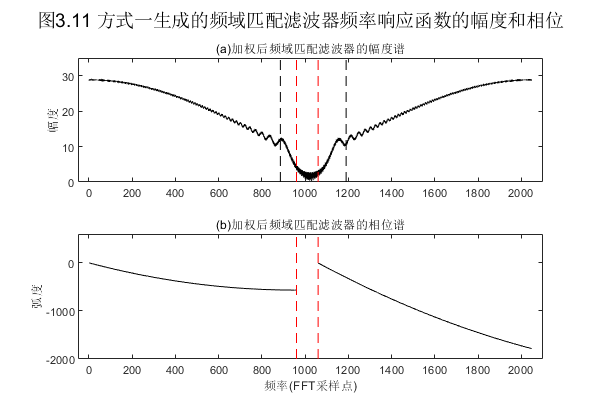

% 参数设置
TBP = 724;             % 时间带宽积
T = 42e-6;             % 脉冲持续时间
Nfft = 2^11;           % FFT长度
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 1.07;       % 过采样率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
df = F/N;              % 采样频率间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
f = -F/2:df:F/2-df;    % 频率变量
% 信号表达
st = exp(1j*pi*K*t.^2);           % Chirp信号复数表达式
Sf = fft((st));                   % Chirp信号频谱表达式
% 窗函数
window = kaiser(N,2.5)';          % 时域窗
Window = fftshift(window);        % 频域窗
% 信号变换
ht = conj(fliplr(st));            % 将时间反褶后的复制脉冲取复共轭
ht_window = window.*ht;           % 加窗
Hf_1 = fft(ht_window,Nfft);       % 计算补零离散傅里叶变换
% 绘图
H = figure;
set(H,'position',[500,500,600,400]);
subplot(211),plot(abs(Hf_1),'k')
axis([-50 2100,0 35])
title('(a)加权后频域匹配滤波器的幅度谱'),ylabel('幅度')
line([886 ,886 ],[0,35],'Color','k','LineStyle','--')
line([1190,1190],[0,35],'Color','k','LineStyle','--')
line([960 ,960 ],[0,35],'Color','r','LineStyle','--')
line([1060,1060],[0,35],'Color','r','LineStyle','--')
subplot(212),plot(1:1:960,unwrap(angle(Hf_1(1:1:960))),'k'),hold on
plot(1060:1:2048,unwrap(angle(Hf_1(1060:1:2048))),'k')
title('(b)加权后频域匹配滤波器的相位谱'),xlabel('频率(FFT采样点)'),ylabel('弧度')
line([960 ,960 ],[-2000,600],'Color','r','LineStyle','--')
line([1060,1060],[-2000,600],'Color','r','LineStyle','--')
axis([-50 2100,-2000 600])
suptitle('图3.11 方式一生成的频域匹配滤波器频率响应函数的幅度和相位')

% sgtitle('图3.11 方式一生成的频域匹配滤波器频率响应函数的幅度和相位','color','k','Fontsize',10)

#### 方式二

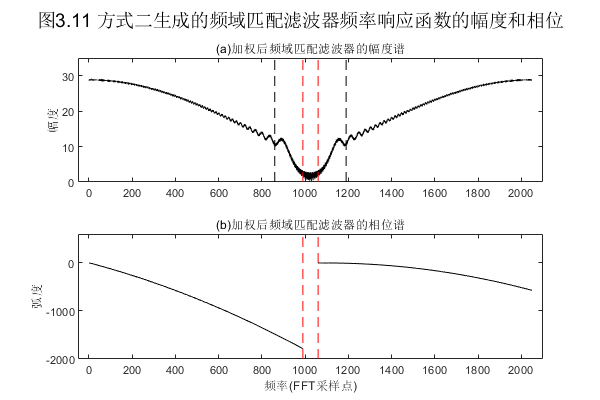

% 参数设置
TBP = 724;             % 时间带宽积
T = 42e-6;             % 脉冲持续时间
Nfft = 2^11;           % FFT长度
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 1.07;       % 过采样率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
df = F/N;              % 采样频率间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
f = -F/2:df:F/2-df;    % 频率变量
% 信号表达
st = exp(1j*pi*K*t.^2);           % Chirp信号复数表达式
Sf = fft((st));                   % Chirp信号频谱表达式
% 窗函数
window = kaiser(N,2.5)';          % 时域窗
Window = fftshift(window);        % 频域窗
% 信号变换
ht = st;                          % 复制信号
ht_window = window.*ht;           % 加窗
Hf_2 = conj(fft(ht_window,Nfft));       % 计算补零离散傅里叶变换
% 绘图
H = figure;
set(H,'position',[500,500,600,400]);
subplot(211),plot(abs(Hf_2),'k')
axis([-50 2100,0 35])
title('(a)加权后频域匹配滤波器的幅度谱'),ylabel('幅度')
line([ 860, 860],[0,35],'Color','k','LineStyle','--')
line([1190,1190],[0,35],'Color','k','LineStyle','--')
line([990 ,990 ],[0,35],'Color','r','LineStyle','--')
line([1060,1060],[0,35],'Color','r','LineStyle','--')
subplot(212),plot(1:1:990,unwrap(-angle(Hf_2(1:1:990))),'k'),hold on
plot(1060:1:2048,unwrap(-angle(Hf_2(1060:1:2048))),'k')
axis([-50 2100,-2000 600])
title('(b)加权后频域匹配滤波器的相位谱'),xlabel('频率(FFT采样点)'),ylabel('弧度')
line([990 ,990 ],[-2000,600],'Color','r','LineStyle','--')
line([1060,1060],[-2000,600],'Color','r','LineStyle','--')
suptitle('图3.11 方式二生成的频域匹配滤波器频率响应函数的幅度和相位')

% sgtitle('图3.11 方式二生成的频域匹配滤波器频率响应函数的幅度和相位','color','k','Fontsize',10)

#### 方式三

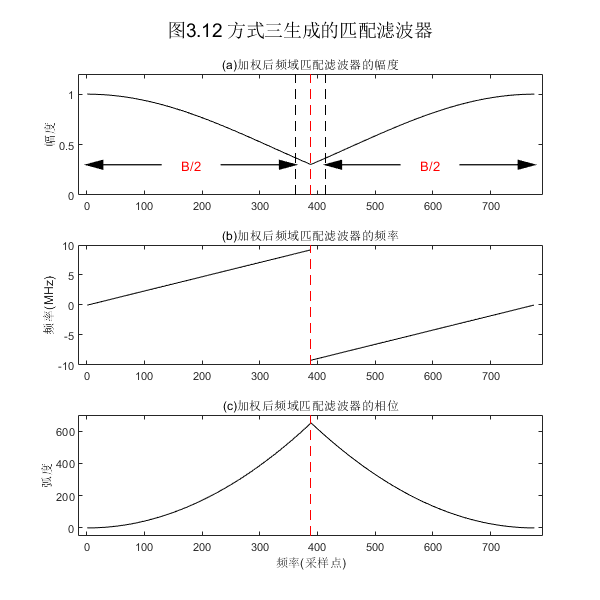

% 参数设置
TBP = 724;             % 时间带宽积
T = 42e-6;             % 脉冲持续时间
Nfft = 2^11;           % FFT长度
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 1.07;       % 过采样率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
df = F/N;              % 采样频率间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
f = -F/2:df:F/2-df;    % 频率变量
% 信号表达
st = exp(1j*pi*K*t.^2);           % Chirp信号复数表达式
Sf = fft((st));                   % Chirp信号频谱表达式
% 窗函数
window = kaiser(N,2.5)';          % 时域窗
Window = fftshift(window);        % 频域窗
% 信号变换
Hf_3 = Window.*exp(1j*pi*f.^2/K); % 计算补零离散傅里叶变换
HF_phi = pi*f.^2/K;               % 频域匹配滤波器的相位
HF_fre = -F/2:df:F/2-df;          % 频域匹配滤波器的频率
% 绘图
H = figure;
set(H,'position',[500,500,600,600]);
subplot(311),plot(abs(Hf_3),'k')
axis([-15 791,0 1.2])
title('(a)加权后频域匹配滤波器的幅度'),ylabel('幅度')
line([362,362],[0,1.2],'Color','k','LineStyle','--')
line([414,414],[0,1.2],'Color','k','LineStyle','--')
arrow([130,0.3],[0  ,0.3],'Color','k','Linewidth',1);
arrow([232,0.3],[362,0.3],'Color','k','Linewidth',1);
text(181,0.3,'B/2','Color','red','HorizontalAlignment','center')
arrow([544,0.3],[414,0.3],'Color','k','Linewidth',1);
arrow([646,0.3],[776,0.3],'Color','k','Linewidth',1);
text(595,0.3,'B/2','Color','red','HorizontalAlignment','center')
line([388,388],[0,1.2],'Color','r','LineStyle','--')
subplot(312),plot(1:1:388,HF_fre(388:1:775)*1e-6,'k'),hold on
plot(388:1:775,HF_fre(1:1:388)*1e-6,'k')
title('(b)加权后频域匹配滤波器的频率'),ylabel('频率(MHz)')
axis([-15 791,-10 10])
line([388,388],[-10 10],'Color','r','LineStyle','--')
subplot(313),plot(fftshift(HF_phi),'k')
title('(c)加权后频域匹配滤波器的相位'),xlabel('频率(采样点)'),ylabel('弧度')
axis([-15 791,-50 700])
line([388,388],[-500,700],'Color','r','LineStyle','--')
suptitle('图3.12 方式三生成的匹配滤波器')

% sgtitle('图3.11 方式二生成的匹配滤波器','color','k','Fontsize',10)

#### 目标定位和匹配滤波器弃置区

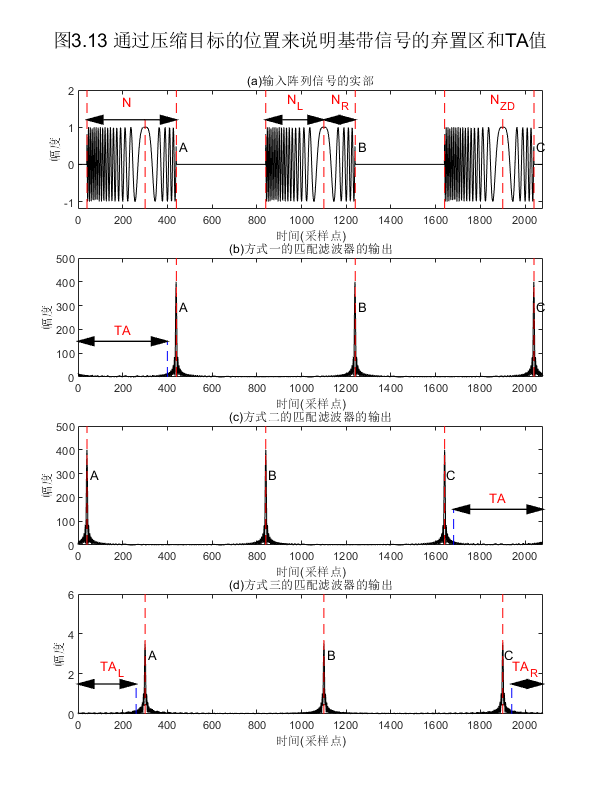

% 参数设置
TBP = 80;              % 时间带宽积
T = 10e-6;             % 脉冲持续时间
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 5;          % 过采样率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
% 参数设置
N_ZD = 60;             % 零频点位于目标中点右侧N_DZ=(N_L-N_R)/2样本处
t_c = N_ZD*dt;         % 脉冲中心相对于t=0的时间偏移
% 信号表达
st1 = exp(1j*pi*K*(t-t_c).^2);                       % 设定长度的线性调频信号
st2 = zeros(1,N);                                    % 设定与信号等长的空信号
st  = [zeros(1,40),st1,st2,st1,st2,st1,zeros(1,40)]; % 实际信号
N_st = length(st);                                   % 实际信号的长度
% 变量设置
n = 0:1:N_st-1;                        % 采样点
f = -F/2:F/N_st:F/2-F/N_st;            % 频率轴      
% 窗函数
window_1 = kaiser(N,2.5)';             % 时域窗
Window_1 = fftshift(window_1);         % 频域窗
% 信号变换-->方式一
ht_1 = conj(fliplr(st1));              % 将时间反褶后的复制脉冲取复共轭
ht_window_1 = window_1.*ht_1;          % 加窗
Hf_1 = fftshift(fft(ht_1,N_st));       % 计算补零离散傅里叶变换
% 窗函数
window_2 = kaiser(N,2.5)';             % 时域窗
Window_2 = fftshift(window_2);         % 频域窗
% 信号变换-->方式二
ht_2 = st1;                            % 复制信号
ht_window_2 = window_2.*ht_2;          % 加窗
Hf_2 = fftshift(conj(fft(ht_2,N_st))); % 计算补零离散傅里叶变换
% 窗函数
window_3 = kaiser(N_st,2.5)';          % 时域窗
Window_3 = fftshift(window_3);         % 频域窗
% 信号变换-->方式三
Hf_3 = Window_3.*exp(1j*pi*f.^2/K);    % 计算补零离散傅里叶变换
% 信号表达
Sf = fftshift(fft(st));
Soutf_1 = Sf.*Hf_1;
soutt_1 = ifft(ifftshift(Soutf_1));    % 方式一匹配滤波结果
Soutf_2 = Sf.*Hf_2;
soutt_2 = ifft(ifftshift(Soutf_2));    % 方式二匹配滤波结果
Soutf_3 = Sf.*Hf_3;
soutt_3 = ifft(ifftshift(Soutf_3));    % 方式三匹配滤波结果
% 绘图
H = figure;
set(H,'position',[100,100,600,800]);
subplot(411),plot(n,real(st),'k')
axis([0 N_st,-1.2 2])
title('(a)输入阵列信号的实部'),xlabel('时间(采样点)'),ylabel('幅度')
text( 470,0.5,'A','Color','black','HorizontalAlignment','center')
text(1270,0.5,'B','Color','black','HorizontalAlignment','center')
text(2070,0.5,'C','Color','black','HorizontalAlignment','center')
line([ 40, 40],[-1.2,2],'Color','r','LineStyle','--')
line([440,440],[-1.2,2],'Color','r','LineStyle','--')
line([300,300],[-1.2,1.3],'Color','r','LineStyle','--')
arrow([310,1.2],[ 40,1.2],'Color','k','Linewidth',1);
arrow([310,1.2],[440,1.2],'Color','k','Linewidth',1);
text(220,1.7,'N','Color','red','HorizontalAlignment','center')
line([ 840, 840],[-1.2,2],'Color','r','LineStyle','--')
line([1240,1240],[-1.2,2],'Color','r','LineStyle','--')
line([1100,1100],[-1.2,1.3],'Color','r','LineStyle','--')
arrow([ 950,1.2],[ 840,1.2],'Color','k','Linewidth',1);
arrow([ 950,1.2],[1100,1.2],'Color','k','Linewidth',1);
arrow([1210,1.2],[1100,1.2],'Color','k','Linewidth',1);
arrow([1210,1.2],[1240,1.2],'Color','k','Linewidth',1);
text( 970,1.7,'N_L','Color','red','HorizontalAlignment','center')
text(1170,1.7,'N_R','Color','red','HorizontalAlignment','center')
line([1640,1640],[-1.2,2],'Color','r','LineStyle','--')
line([2040,2040],[-1.2,2],'Color','r','LineStyle','--')
line([1900,1900],[-1.2,1.3],'Color','r','LineStyle','--')
text(1900,1.7,'N_{ZD}','Color','red','HorizontalAlignment','center')
subplot(412),plot(n,abs(soutt_1),'k')
axis([0 N_st,0 500])
title('(b)方式一的匹配滤波器的输出'),xlabel('时间(采样点)'),ylabel('幅度')
text( 470,300,'A','Color','black','HorizontalAlignment','center')
text(1270,300,'B','Color','black','HorizontalAlignment','center')
text(2070,300,'C','Color','black','HorizontalAlignment','center')
line([ 440, 440],[0,500],'Color','r','LineStyle','--')
line([1240,1240],[0,500],'Color','r','LineStyle','--')
line([2040,2040],[0,500],'Color','r','LineStyle','--')
line([ 400, 400],[0,150],'Color','b','LineStyle','--')
arrow([ 200,150],[  0,150],'Color','k','Linewidth',1);
arrow([ 200,150],[400,150],'Color','k','Linewidth',1);
text( 200,200,'TA','Color','red','HorizontalAlignment','center')
subplot(413),plot(n,abs(soutt_2),'k')
axis([0 N_st,0 500])
title('(c)方式二的匹配滤波器的输出'),xlabel('时间(采样点)'),ylabel('幅度')
text(  70,300,'A','Color','black','HorizontalAlignment','center')
text( 870,300,'B','Color','black','HorizontalAlignment','center')
text(1670,300,'C','Color','black','HorizontalAlignment','center')
line([  40,  40],[0,500],'Color','r','LineStyle','--')
line([ 840, 840],[0,500],'Color','r','LineStyle','--')
line([1640,1640],[0,500],'Color','r','LineStyle','--')
line([1680,1680],[0,150],'Color','b','LineStyle','--')
arrow([1840,150],[2080,150],'Color','k','Linewidth',1);
arrow([1840,150],[1680,150],'Color','k','Linewidth',1);
text(1880,200,'TA','Color','red','HorizontalAlignment','center')
subplot(414),plot(n,abs(soutt_3),'k')
axis([0 N_st,0   6])
title('(d)方式三的匹配滤波器的输出'),xlabel('时间(采样点)'),ylabel('幅度')
text( 330,3,'A','Color','black','HorizontalAlignment','center')
text(1130,3,'B','Color','black','HorizontalAlignment','center')
text(1930,3,'C','Color','black','HorizontalAlignment','center')
line([ 300, 300],[0,6],'Color','r','LineStyle','--')
line([1100,1100],[0,6],'Color','r','LineStyle','--')
line([1900,1900],[0,6],'Color','r','LineStyle','--')
line([ 260, 260],[   0,1.5],'Color','b','LineStyle','--')
arrow([ 150,1.5],[   0,1.5],'Color','k','Linewidth',1);
arrow([ 150,1.5],[ 260,1.5],'Color','k','Linewidth',1);
text( 150,2.3,'TA_L','Color','red','HorizontalAlignment','center')
line([1940,1940],[   0,1.5],'Color','b','LineStyle','--')
arrow([2000,1.5],[2080,1.5],'Color','k','Linewidth',1);
arrow([2000,1.5],[1940,1.5],'Color','k','Linewidth',1);
text(2000,2.3,'TA_R','Color','red','HorizontalAlignment','center')
suptitle('图3.13 通过压缩目标的位置来说明基带信号的弃置区和TA值')

% sgtitle('图3.11 方式二生成的匹配滤波器','color','k','Fontsize',10)

#### 调频率失配

调频率K的误差会引起滤波器的失配，是的IRW展宽，旁瓣增大。